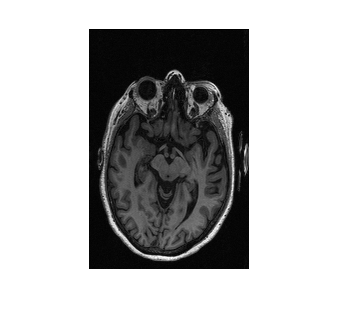

%Load the image
ImSegment = load("segmentData.mat");
ImSegment = ImSegment.data;
figure();
imshow(ImSegment, [])

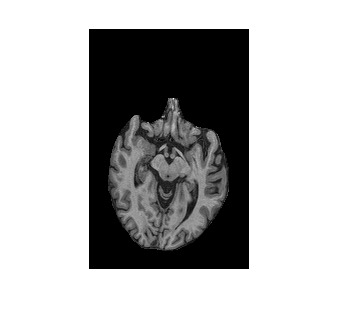

Im = load("correctedData.mat");
Im = Im.correctedData;
imshow(Im, []);

ImVals = Im(Im > 0);
%Plot the histogram
figure();
histogram(ImVals, 100, "Normalization", "pdf");
hold on;
ImMin = min(ImVals)

ImMin = 17.0782

ImMax = max(ImVals)

ImMax = 549.6669

ImR = range(ImVals)

ImR = 532.5887

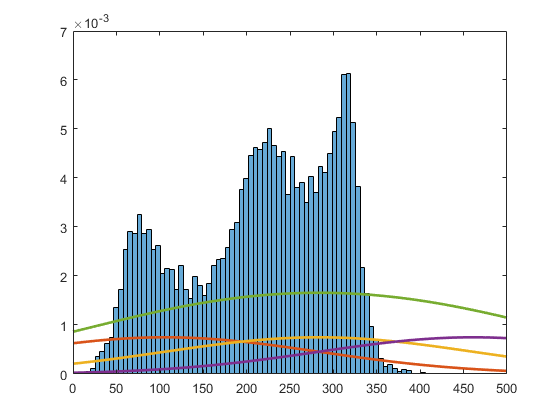

%Define the priors
pi = [1 1 1] / 3;
%Divide the range into 3 equal intervals
I1 = [ImMin ImMin + ImR / 3];
I2 = [ImMin + ImR / 3 ImMin + 2 * ImR / 3];
I3 = [ImMin + 2 * ImR / 3 ImMin + ImR];
%Define the initial means as the centers of the intervals
mu = mean([I1; I2; I3], 2)';
%Define the stamdard deviations as the width of the intervals
sigma = ones([1 3]) * (ImR / 3);
%Plot the histogram together with the 3 distributions
x = (0:1:500);
GaussComb = 0;
for i = 1:3
    plot(x, pi(i) * normpdf(x, mu(i), sigma(i)), "LineWidth", 2);
    GaussComb = GaussComb + pi(i) * normpdf(x, mu(i), sigma(i));
end
plot(x, GaussComb, "LineWidth", 2)
xlim([0 500])
hold off;

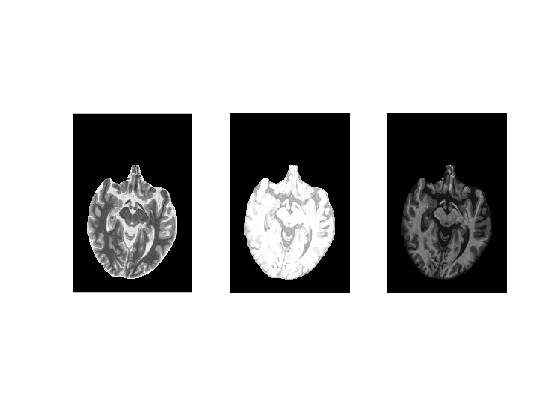


%Obtain weights 
weights = zeros([length(ImVals) 3]);

%Define the normalizing constant
normConst = 0;
for i = 1:3
    normConst = normConst + normpdf(ImVals, mu(i), sigma(i)) * pi(i);
end
%Obtain the weights (posteriors)
for i = 1:3
    weights(:, i) = (pi(i) * normpdf(ImVals, mu(i), sigma(i))) ./ normConst;
end

%Visualize the weights (posteriors)
ImPost = Im;
figure();
for i = 1:3
    subplot(1, 3, i);
    ImPost((ImPost > 0)) = weights(:, i);
    imshow(ImPost, [])
end

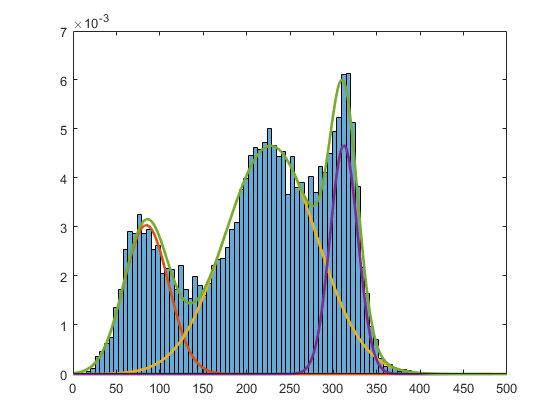


%Perform 100 iterations of updating the parameters
logLikelihood = zeros([1 100]);
for k = 1:100
    mu = sum(weights .* ImVals, 1) ./ sum(weights, 1);
    sigma = sqrt(sum(weights .* (ImVals - mu).^2, 1) ./ sum(weights, 1));
    pi = sum(weights, 1) / length(ImVals);
    normConst = 0;
    for i = 1:3
        normConst = normConst + pi(i) * normpdf(ImVals, mu(i), sigma(i));
    end
    for i = 1:3
        weights(:, i) = (pi(i) * normpdf(ImVals, mu(i), sigma(i))) ./ normConst;
    end
    logLikelihood(k) = sum(weights .* log((normpdf(ImVals, mu, sigma) .* pi) ./ weights), "all");
end

%Visualize the results
%Plot the histogram again along with the 3 density functions
figure();
histogram(ImVals, 100, "Normalization", "pdf");
hold on;
x = (0:1:500);
GaussComb = 0;
for i = 1:3
    plot(x, pi(i) * normpdf(x, mu(i), sigma(i)), "LineWidth", 2);
    GaussComb = GaussComb + pi(i) * normpdf(x, mu(i), sigma(i));
end
%Plot the combined density function
plot(x, GaussComb, "LineWidth", 2)
xlim([0 500])
hold off;

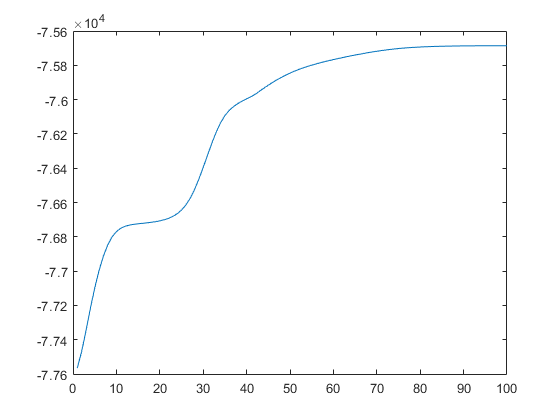


%Visualize the log-likelihood function
figure();
plot(logLikelihood);

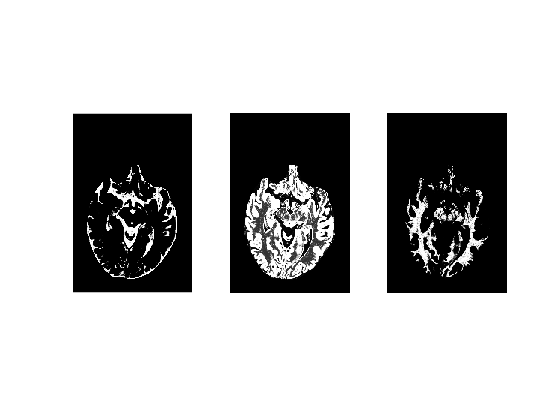


figure();
for i = 1:3
    subplot(1, 3, i);
    ImPost((ImPost > 0)) = weights(:, i);
    imshow(ImPost, [])
end